%Controller design
A = [0 1 0;0 -1 1;1 0 0];
B = [0;1;0];
poles = [-1 -1 -1]

poles =     -1    -1    -1


%Finding gain matrix using Ackerman pole placement
K = Ackermann(A,B,poles)

K =      3     2     2


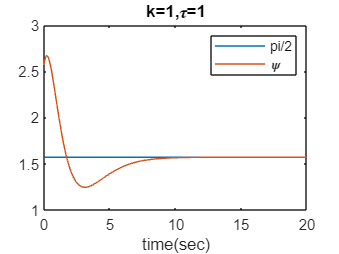

tstart = 0;
tend = 20;
dt = 0.01;
n = 1000;

tspan = transpose(linspace(tstart,tend,n));
xinit = [1 1 0];  %initial values of [x1 x2 sigma]

[t,x] = ode45(@integratingfunc_SpringMass_system, tspan, xinit);
plot(t,zeros(size(tspan))+(pi/2),t,x(:,1)+(pi/2))
title("k=1,\tau=1")
legend(["pi/2","\psi"])
xlabel("time(sec)")

function dxdt = integratingfunc_SpringMass_system(t,x)
%INTEGRATINGFUNC_SPRINGMASS_SYSTEM Summary of this function goes here
%   Detailed explanation goes here
k_act = 1;
tau_act = 1;
A = [0 1 0;0 (-1/tau_act) (k_act/tau_act);1 0 0];
B = [0;k_act/tau_act;0];
K = [3 2 2];

dxdt = (A-(B*K))*x;
end

%Ackermann function for pole placement
function K = Ackermann(Ac,Bc,poles)

n = size(Ac,1);
m = size(Bc,2);
In = eye(n);
del_A = eye(n);
%Forming characteristic equation
for i=1:n
    del_A = del_A*(Ac-(poles(i)*In));
end
const = zeros(1,n);
const(1,n) = 1;

%Forming controllability matrix
iter = Ac*Bc;
    con = [Bc iter];
    for i = 1:n-2
        iter = Ac*iter;
        con = [con iter];
    end
K = const*(con\del_A);      % For SISO K = [0 0 ...1]*inv(con)*A_desired

end


